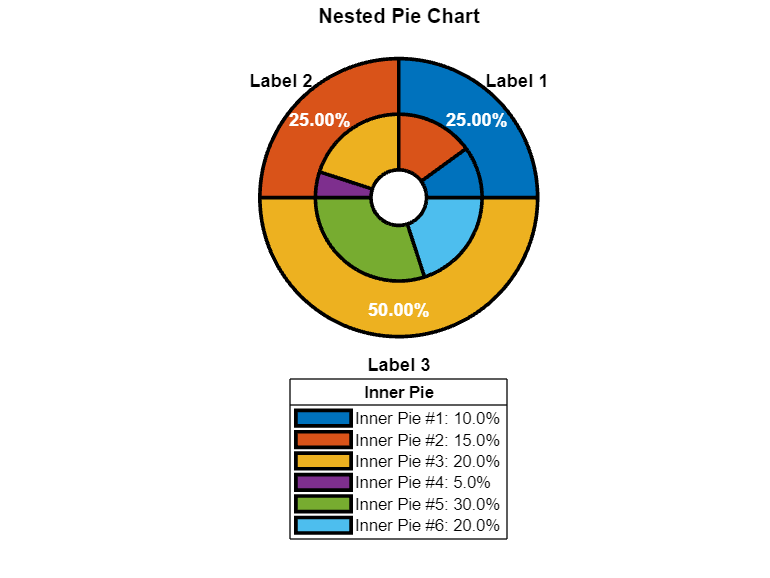

% Example 1: Nested pie chart

% Initialize data points
inner_pie = [0.1, 0.15, 0.2, 0.05, 0.3, 0.2];
outer_pie = [0.25, 0.25, 0.5];
C = {...
    inner_pie,... % Inner pie must come first!
    outer_pie};

% Spider plot
pie_nested(C);

% Title
title('Nested Pie Chart');

% Legend properties
legend_str = cell(length(inner_pie), 1);
for ii = 1:length(legend_str)
    inner_value = inner_pie(ii);
    legend_str{ii} = sprintf('Inner Pie #%i: %.1f%%', ii, inner_value*100);
end
lg =legend(legend_str, 'Location', 'southoutside');
lg.Title.String = 'Inner Pie';